clc % clear command window
clear all % clear workspace

1. Supply path to the toolkit's "model_code" directory to "cfg" structure, and add the "common" subfolder to the MATLAB path. Also specify the general directory where results will be saved. 

% Add paths to relevant functions
cfg.model_dir = '/Shared/boeslab/Users/jcgriffis/ibb_modeling_toolkit/model_code'; % path to toolkit
addpath(genpath(fullfile(cfg.model_dir, 'common'))); % add common folder to path

% Specify output directory (Note - output folders for specific analyses will be created in this directory)
out_dir = '/Shared/boeslab/Users/jcgriffis/toolkit_paper_analyses/tutorial_results';

2. To perform a lesion-mapping/lesion-modeling analysis, specify that the modality is "lesion", and supply a path to a brain mask that is 

co-registered to the same template as your lesion data and that has the same image and voxel dimensions as your lesion data.

% Specify data modality and supply brain mask
cfg.modality = 'lesion'; % predictor modality - 'lesion' or 'other' 
cfg.mask_path = fullfile('/Shared/boeslab/Data/Lesion/Iowa/Registry/derivedData/LesionQuantificationToolkit/Chronic/Yeo7200/Lesion_3mm/mask/brain_mask.nii'); % path to brain mask

3. Specify general modeling options.

- cfg.model_spec - the type of model you want to fit. To run a LASSO reression, set to 'lasso'.

- cfg.fit_explanatory_model - flag indicating whether you want to fit a model to the full dataset to test significance of model coefficients. For inferential (e.g., lesion-symptom mapping) analyses, turn this on. Note that the model is explanatory, not predictive. 

- cfg.optimize_hyperparams - flag indicating whether you want to use cross-validation to optimize model hyper-parameters. For multivariate models, this is recommended.

- cfg.cross_validation - flag indicating whether you want to use cross-validation to estimate predictive performance and out-of-sample generalization. If hyper-parameter optimization is selected, then this will perform nested cross-validation. For predictive analyses, turn this on. Note that significance testing is not performed on model coefficients/maps. 

- cfg.bootstrap - flag indicating whether you want to use bootstrapping to estimate statistical significance of model coefficients and/or to estimate confidence intervals for multivariate explanatory models. Recommended if fitting multivariate explanatory model.

- cfg.permutation - flag indicating whether you want to use permutation testing to estimate statistical significance of model fit and/or model coefficients. Recommended.

These options will be used to initialize an analysis with default parameters for the selected options by supplying the cfg structure as an input to the function get_default_model_cfg(), which automatically populates the cfg structure with default settings for the specified modeling options, and returns the populated cfg structure. 

% Specify general modeling options
cfg.model_spec = 'lasso'; % model to fit
cfg.fit_explanatory_model = 1; % fit explanatory model to full dataset 
cfg.optimize_hyperparams = 1; % use cross-validation to optimize model hyperparameters
cfg.cross_validation = 1; % use cross-validation to estimate out-of-sample predictive performance
cfg.bootstrap = 1; % use bootstrap resampling for significance testing of coefficients
cfg.permutation = 1; % use permutation testing for significance testing of model fit (and/or coefficients)

% Initialize cfg file with default settings given general modeling options
cfg = get_default_model_cfg(cfg); 

cfg.jackknife field is empty; setting to 0 with default settings
Analysis type is lesion - setting defaults


4. Specify paths to behavioral and lesion data, and load and format data into predictor matrix and response array. The behavioral CSV file should include a "study_id" column containing patient IDs and a second column containing behavioal scores. Also specify the path to the directory containing the lesion images. Lesion images for all patients should be in the same folder. Note: IDs in "study_id" column must match file prefixes for lesion data - e.g., if the "study_id" for patient 1 is "0001", then their lesion file should be "0001.nii.gz". There must be a lesion image for all subjects with non-missing behavioral data.

The function get_and_format_lesion_data() adds several fields to the cfg structure: 

- cfg.X - subject-by-voxel lesion predictor matrix 

- cfg.lvol - subject-by-1 array of lesion volumes

- cfg.Y - subject-by-1 array of behavioral scores

- cfg.include_subs - string array of subject IDs that had non-missing behavioral data and that were included in the analysis.

% Specify path to CSV containing study IDs and behavioral scores
beh_csv = readtable('/Shared/boeslab/Users/jcgriffis/toolkit_paper_analyses/behavior/test_data.csv'); % read in CSV file as table
id_col = 'study_id'; % name of column containing 4-digit IDs
beh_col = 'mae_token'; % name of column containing behavior of interest

% Specify lesion directory and indicate whether patients are registry patients
lesion_dir = '/Shared/boeslab/Data/Lesion/Iowa/Registry/derivedData/LesionQuantificationToolkit/Chronic/Yeo7200/Lesion_3mm'; % directory containing lesion images
registry_flag = 1; % CSV contains numeric registry IDs (i.e., '0's need to be appended for subjects < 1000)

% Get formatted lesion matrix, behavioral data, subject IDs, and mask volume/header and in-mask indices
% Note: outputs are stored as fields in cfg structure 
cfg = get_and_format_lesion_data(beh_csv, id_col, beh_col, registry_flag, lesion_dir, cfg);

All subjects with behavioral data have lesion files, N=282 patients will be included


% Invert behavioral scores so that more positive values -> worse performance 
cfg.Y = cfg.Y.*-1; 

5. Modify any default settings as relevant to the analysis. Here, we increase the frequency threshold from the default (4) to 10, turn on the DTLVC procedure, turn on standardization of the outcome variable, set the number of bootstrap/permutation iterations, and set the number of folds and repeats used for hyper-parameter optimization and cross-validation. We also standardize the outcome variable and specify that we want to stratify train/test splits based on the outcome variable distribution. We also indicate that we want this to be a "stackable" prediction model, so we don't want to drop subjects that only have zero-valued predictor data, and we want to pre-generate train/test partitions before running any models. See the function get_default_model_cfg() for all default parameter values. 

% Customize analysis parameters

% Lesion-mapping
cfg.freq_thresh = 10; % only include voxels that are lesioned in at least 10 patients
cfg.dtlvc = 0; % Use direct total lesion volume control (Zhang et al., 2014)

% Variable standardization
cfg.standardize = 0; % Standardize X & Y since ridge regression penalizes based on coefficient magnitudes (1 - standardize X & Y, 2 - standardize only Y)

% Statistical significance testing 
cfg.boot.n_boot = 1000; % bootstrap iterations
cfg.perm.n_perm = 1000; % permutation iterations

% Hyper-parameter optimization
cfg.hp_opt.cv_type = 'KFold'; % Do K-fold cross-validation for hyper-parameter optimization
cfg.hp_opt.folds = 2; % split-half cross-validation
cfg.hp_opt.repeats = 5; % 5 repeats of split-half cross-validation

% Cross-validation
cfg.cv.cv_type = 'KFold'; % Do K-Fold cross-validation
cfg.cv.folds = 5; % 5-fold cross-validation
cfg.cv.repeats = 5; % 5 runs of 5-fold cross-validation
cfg.cv.permutation = 0; % Do permutation testing of cross-validation (turned off for this tutorial to save time)
cfg.cv.n_perm = 0; % do 0 permutations (at least 20 are recommended, this is the minimum to achieve p<0.05)
cfg.cv.stacked_model = 1; % Don't drop subjects with no non-zero predictor data 

% Stratification for cross-validation 
cfg.strat_var = cfg.Y; % Stratify partitions

6. Specify the specific folder where analysis results should be saved. Note - if the output folder specified in cfg.out_dir doesn't exist, it will be created automatically once the analysis is run.

% Specify output directory
cfg.out_dir = fullfile(out_dir, [cfg.model_spec '_' beh_col '_lesion_d' num2str(cfg.dtlvc) '_s' num2str(cfg.standardize)]);

7. Supply the fully-specified cfg structure as input to the function fit_and_evaluate_model(), which executes the modeling analysis specified in the cfg structure. This returns a new structure, model_results, which contains the results of the modeling analysis along with the original cfg file (as a sub-structure) for reproducibility. This structure is saved by default in the folder specified by cfg.out_dir. If cross-validation was performed, a second structure named cv_results, which contains the results of the cross-validation analyses, will be saved in the file "cv_results.mat" within the output directory specified by cfg.out_dir. 

% fit model with CV hyperparameter optimization and selected significance testing
[model_results] = fit_and_evaluate_model(cfg);

Trimming data to retain columns with at least 10 observations greater than or equal to 1
group 1:86
group 2:69
group 3:57
group 4:70
Preallocating CV results
Outer CV repeats:1/5
Running 5 repeats of 2-fold optimization for model hyperparameters
Hyper-parameter optimization iteration:1/5
Hyper-parameter optimization iteration:2/5
Hyper-parameter optimization iteration:3/5
Hyper-parameter optimization iteration:4/5
Hyper-parameter optimization iteration:5/5
Optimal lambda = 0.0002804, fitting model with optimal lambda
Running 5 repeats of 2-fold optimization for model hyperparameters
Hyper-parameter optimization iteration:1/5
Hyper-parameter optimization iteration:2/5
Hyper-parameter optimization iteration:3/5
Hyper-parameter optimization iteration:4/5
Hyper-parameter optimization iteration:5/5
Optimal lambda = 0.0006033, fitting model with optimal lambda
Running 5 repeats of 2-fold optimization for model hyperparameters
Hyper-parameter optimization iteration:1/5
Hyper-parameter optimiz

Evaluating tall expression using the Parallel Pool 'Processes':
- Pass 1 of 1: Completed in 1.9 sec
Evaluation completed in 3.5 sec
Evaluating tall expression using the Parallel Pool 'Processes':
- Pass 1 of 1: Completed in 0.73 sec
Evaluation completed in 0.79 sec
Thresholding betas based on CI widths....
Finished running modeling analysis
Time to to complete:1.32 minutes


8. View model results structure to evaluate model performance measures. The different fields contain different details about analysis parameters, data, and results.

- has_data - logical array of length n_subjects with values of 1 for all patients that were included in the analysis. If cfg.stacked_model were set to 0, then some patients could be dropped due to not having any data after removing voxels that met the minimum damage frequency threshold, and this can be used to identify which patients were dropped and which patients were retained for the analysis. If patients were dropped, then model_results.obs_y, model_results.pred_y, and model_results.X would have fewer rows than this field. 

- coeff - model coefficients (i.e., beta weights) for each voxel included in the model.

- beta0 - intercept for ridge regression model

- Lambda - optimized lambda value used for the inferential ridge regression model

- pred_y - fitted behavioral scores from the full-sample model (i.e., within-sample model "predictions"). These are always in the scale of the original data, even if standardization is performed.

- r2 - explained variance in the full sample (i.e., model R-squared) calculated using the "sum-of-squares" formula.

- mse - model mean squared error

- obs_y - observed behavioral scores. These are always in the scale of the original data, even if standardization is performed

- perm - subfield containing results from permutation testing

- boot - subfield containing results from bootstrap analyses

- X - final predictor matrix after trimming columns with insufficient data

- X_ind - indices mapping the columns in the final predictor matrix model_results.X to the colulmns in the original predictor matrix cfg.X, i.e., the columns included in model_results.X are given by: model_results.X = cfg.X(model_results.X_ind).

- rng_seed - RNG seed and state for reproducibility

- cfg - the cfg structure containing analysis parameters and details for reproducibility

- methods_text - text description of methods details. Also saved as .txt file in output directory

- results_text - text description of results details. Also saved as .txt file in output directory

% View contents of model_results structure
model_results

model_results = struct with fields:
        has_data: [282×1 double]
          pred_y: [282×1 single]
           obs_y: [282×1 double]
              r2: 0.4043
             mse: 78.0927
           coeff: [13786×1 single]
           beta0: -42.0906
          Lambda: 2.2301e-05
            perm: [1×1 struct]
            boot: [1×1 struct]
               X: [282×13786 single]
           X_ind: [13786×1 double]
        rng_seed: {[0]  'twister'}
             cfg: [1×1 struct]
    methods_text: 'Data were modeled using L1-regularized (LASSO) regression. Only predictors with at least 10 non-zero observations with absolute values greater than 1 were included in the analysis. N=282 observations were included in the analysis. An inferential model was fit to the full dataset.  Hyper-parameter optimization was performed to determine the regularization parameter (lambda) using 5 repetitions of 2-fold cross-validation with repartitioning at each repetition. To determine the significance of the infe

By accessing fields in the model_results structure, you can evaluate the fit of the explanatory model. Note - these are *not* prediction performance estimates because these are from the full-sample model, and can be influenced by over-fitting. Prediction performance estimates are in the cv_results structure saved into the output directory

% Display model fit for in-sample explanatory model
disp(['Explanatory Model R-squared: ' num2str(model_results.r2)]);

Explanatory Model R-squared: 0.4043


% Evaluate model significance from permutation testing
disp(['Permutation p-value: ' num2str(model_results.perm.model_pval)]);

Permutation p-value: 0.000999


% Evaluate 95% CIs from bootstrapping
disp(['95% CI on R-squared: ' num2str(model_results.boot.r2_ci')]);

95% CI on R-squared: 0.18749     0.52666


The permutation p-value indicates that the model fit is statistically significant.

Cross-validation test results and prediction performance estimates are in the cv_results structure saved into the output directory. We can load the cv_results.mat file to evaluate the cross-validation test results. 

% Load cross-validation results for cross-validation test results
load(fullfile(cfg.out_dir, 'cv_results.mat'));

% Display model fit statistics from full sample cross-validation test results
disp(['Full-Sample Cross-validation Correlation: r=' num2str(cv_results.all.corr) ', p=' num2str(cv_results.all.corr_pval)]);

Full-Sample Cross-validation Correlation: r=0.61905, p=3.1767e-31


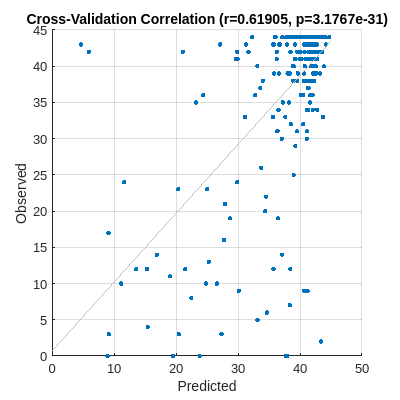

% Plot mean predicted out-of-fold values vs. observed values
clf;
scatter(mean(cv_results.all.pred_y.*-1,2), cv_results.all.obs_y.*-1, 50, '.'); lsline;
grid on; xlabel('Predicted'); ylabel('Observed'); title(['Cross-Validation Correlation (r=' num2str(cv_results.all.corr) ', p=' num2str(cv_results.all.corr_pval) ')']);
set(gcf, 'position', [0, 0, 400, 400]);

The full sample cross-validation correlation is highly significant (p<0.001), supporting interpretation of the model. 

9. To evaluate *prediction* performance, load the cv_results.mat file from the output directory and view the contents.

- train_set - subject-by-repeat-by-fold matrix of 1's and 0's. For each pairing of repeat and fold (e.g., repeat 1 fold 3 would be train_set(:, 1, 3), patients included in the training set have values equal to 1, and patients not in the training set for that fold for that repeat have values equal to 0.

- test_set - subject-by-repeat-by-fold matrix of 1's and 0's. For each pairing of repeat and fold (e.g., repeat 1 fold 3 would be test_set(:, 1, 3), patients included in the test set have values equal to 1, and patients not in the test set for that fold for that repeat have values equal to 0.

- beta_0 - repeat-by-fold matrix of intercepts from the models fit to the training sets. Here, there were 5 repeat of 5-fold cross-validation, so beta_0 is a 5x5 array.

- lambda - repeat-by-fold matrix of optimized lambda values from the nested cross-validation 

- avg - subfield containing model coefficients and performance estimates averaged across folds (note: median is used instead of mean if cfg.cv.summary_type = 'median')

- coeff - n_voxels-by-repeat-by-fold matrix of model coefficients, analogous to the corresponding field in model_results

- all - subfield containing out-of-fold predictions for all observations for each repeat, along with cross-validation test results (correlation of predicted and observed computed using average [across repeats] of out-of-fold predictions for all observations)

- pred_y - n_subjects-by-repeat-by-fold matrix of predicted behavioral scores for each test set in each fold and each repeat. For each fold within each repeat, patients that were in the training set have values equal to NaN, while patients in the test set have values equal to their predicted behavioral scores. 

- obs_y - same as pred_y, but with observed scores.

- explained - repeat-by-fold matrix of R-squared values for each test set computed using the explained variance score method. 

- r2_ss - repeat-by-fold matrix of R-squared values for each test set computed using the sum-of-squares method. 

- mse - repeat-by-fold matrix of mean squared error values for each test set. 

- corr - repeat-by-fold matrix of Pearson correlation values between predicted and observed scores for each test set.

- perm_pval - permutation p-value for mean (or median depending on value of cfg.cv.summary_type) cross-validation MSE (would be present if cfg.cv.permutation were set to 1)

% Load cv_results to evaluate out-of-sample prediction
load(fullfile(cfg.out_dir, 'cv_results.mat'));
cv_results

cv_results = struct with fields:
    train_set: [282×5×5 double]
     test_set: [282×5×5 double]
       beta_0: [5×5 double]
       lambda: [5×5 double]
          avg: [1×1 struct]
        coeff: [13786×5×5 double]
          all: [1×1 struct]
       pred_y: [282×5×5 double]
        obs_y: [282×5×5 double]
    explained: [5×5 double]
        r2_ss: [5×5 double]
          mse: [5×5 double]
         corr: [5×5 double]


We can plot the explained variance for the held-out patients across folds of the cross-validation. The left plot shows the mean across folds for each repetition of the cross-validation. The right plot shows the distribution of R-squared values across all folds and repeats of the cross-validation (boxplot) along with the mean cross-validation R-squared (black dot) and the 95% CIs (red error bars) from the inerential model for comparison. 

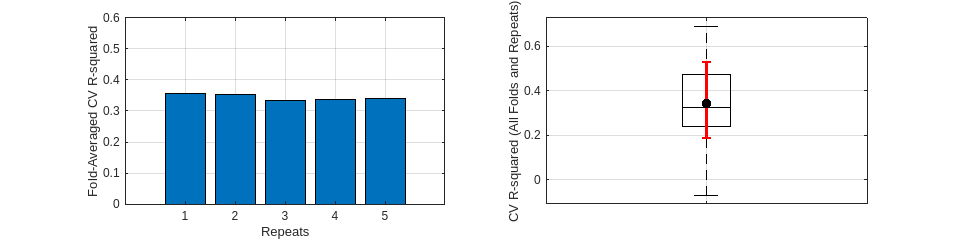

% Plot explained variance across folds
clf;
subplot(1,2,1); 
bar(cv_results.avg.r2_ss(:)); grid on;
hold on; ylabel('Fold-Averaged CV R-squared');
set(gca, 'YLim', [0, .6]); set(gca, 'XtickLabel', {'1', '2', '3', '4', '5'}); xlabel('Repeats')
subplot(1,2,2);
boxplot(cv_results.r2_ss(:), 'Colors', 'k');
hold on; ylabel('CV R-squared (All Folds and Repeats)');
set(gca, 'XtickLabel', '');hold on; 
% Plot in-sample model fit and 95% CIs from inferential model
errorbar(1, model_results.r2, model_results.r2-model_results.boot.r2_ci(1), model_results.boot.r2_ci(2)-model_results.r2, 'Color', 'r', 'LineWidth', 2);
plot(mean(cv_results.r2_ss(:)), 'Marker', '.', 'MarkerSize', 25, 'MarkerEdgeColor', 'k'); set(gcf, 'position', [0, 0, 1000, 250]); grid on;

9. Save explanatory model coefficients as NIFTI images (i.e., as lesion-symptom maps). NIFTI images containing model coefficients will be saved in the output directory specified by cfg.out_dir. If bootstrapping and/or permutation testing was performed for model weights, then result images will be saved into sub-folders named "Bootstrap_Result_Images" and "Permutation_Result_Images", respectively. 

% Map model coefficients back to the in-brain voxels of the 3D MNI volume using MATLAB NIFTI I/O functions
disp('Saving beta weight maps as NIFTI images...');

Saving beta weight maps as NIFTI images...


write_model_weight_maps(model_results);

    0.0500



disp('Done')

Done
